Comparison of Fourier coefficients between 180 to 360 degree fit

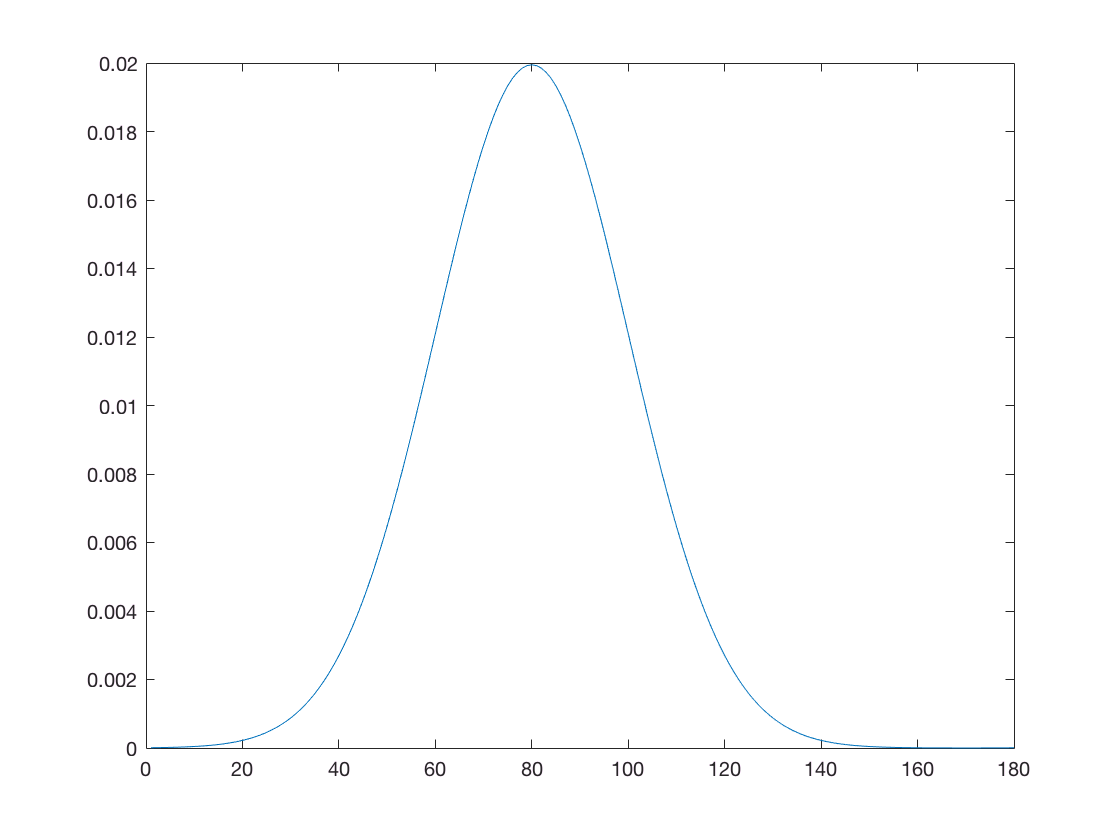

clear all
close all
clc
addpath(genpath('..'));

%% Data set informaton
theta180 = 1:1:180;
theta360 = 1:1:360;
data_raw = [27 33 40 48 58 70 84 101 121 144 171 203 240 283 333 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22 27 33 40 48 58 70 84 101 121 144 171 203 240 283 334 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22];
data_avg = (data_raw(1:180) + data_raw(181:360))/2;

ndata180 = data_avg/sum(data_avg);
ndata360 = data_raw/sum(data_raw);

figure
plot(theta180, ndata180);

Fit to Fourier Model

fs_order = 14;

warning('off','all')

fit180 = fitToFourierModel(fs_order,theta180',ndata180');
fit360 = fitToFourierModel(fs_order,theta360',ndata360');

Compare coefficients

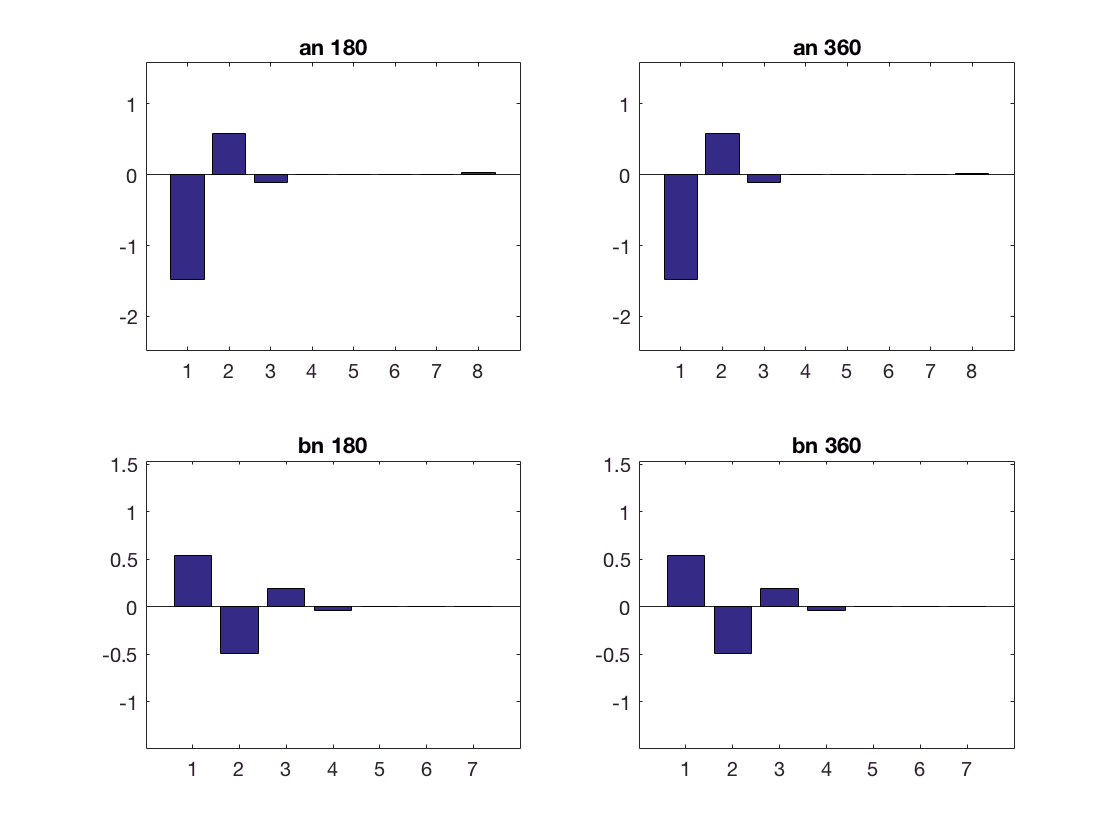

warning('off','all')
coeff_180 = coeffvalues(fit180);
an_180 = coeff_180(1:2:length(coeff_180));
bn_180 = coeff_180(2:2:length(coeff_180));

coeff_360 = coeffvalues(fit360);
an_360 = coeff_360(1:2:length(coeff_360));
bn_360 = coeff_360(2:2:length(coeff_360));

figure
subplot(2,2,1, 'replace');
bar(1:length(an_180),an_180)
axis([0,length(an_180)+1,min(an_180)-1,max(an_180)+1]);
title('an 180');
subplot(2,2,2,'replace');
bar(1:length(an_360),an_360)
axis([0,length(an_360)+1,min(an_360)-1,max(an_360)+1]);
title('an 360');
subplot(2,2,3,'replace');
bar(1:length(bn_180),bn_180)
axis([0,length(bn_180)+1,min(bn_180)-1,max(bn_180)+1]);
title('bn 180');
subplot(2,2,4,'replace');
bar(1:length(bn_360),bn_360)
axis([0,length(bn_360)+1,min(bn_360)-1,max(bn_360)+1]);
title('bn 360');